# Analiza zbioru Quarterly Government Debt (Kwartalny Dług Publiczny)

Dane są podane w milionach jednostek waluty krajowej.

clear; clc; close all;

## 1. Wczytanie danych z Excela

W arkuszu występują metadane i struktura "co druga kolumna".

fileName = 'zbior.xlsx';
sheetName = 'Sheet 1';
raw = readcell(fileName, 'Sheet', sheetName);

% Kwartały znajdują się w dziesiatym wierszu
timeCols = 2:2:size(raw,2);
quarters = string(raw(10, timeCols));
quarters = strtrim(quarters);
quarters = quarters(~ismissing(quarters) & quarters ~= "");

% Kraje zaczynają się od wiersza 12
startRow = 12;
geoLabels = string(raw(:,1));
geoLabels = strtrim(geoLabels);

ignoreLabels = [ ...
    "GEO (Labels)", ...
    "European Union - 27 countries (from 2020)", ...
    "Euro area – 21 countries (from 2026)", ...
    "Euro area – 20 countries (2023-2025)", ...
    "Euro area - 19 countries  (2015-2022)", ...
    "Special value", "Observation flags:", ":", "p", "" ];

countryMask = false(size(raw,1),1);
for r = startRow:size(raw,1)
    label = strtrim(string(raw{r,1}));
    if ~ismember(label, ignoreLabels) && label ~= "<missing>"
        countryMask(r) = true;
    end
end

countryRows = find(countryMask);
countries = strtrim(string(raw(countryRows,1)));
countries = countries(~ismissing(countries));


fprintf('Załadowano %d krajów i %d kwartałów.\n', numel(countries), numel(quarters));

Załadowano 28 krajów i 55 kwartałów.


fprintf('Zakres czasu: %s do %s.\n', quarters(1), quarters(end));

Zakres czasu: 2012-Q1 do 2025-Q3.


## 2. Konwersja danych do macierzy numerycznej

Wartości zadłużenia są w tych samych kolumnach, w których są kwartały. Tworzona jest macierz: wiersze = kraje, kolumny = kwartały.

debtValues = NaN(numel(countries), numel(quarters));

for i = 1:numel(countryRows)
    rowVals = raw(countryRows(i), timeCols(1:numel(quarters)));
    for j = 1:numel(quarters)
        x = rowVals{j};
        if isnumeric(x) && ~isempty(x)
            debtValues(i,j) = x;
        elseif ischar(x) || isstring(x)
            debtValues(i,j) = str2double(string(x));
        end
    end
end

missingShare = mean(isnan(debtValues), 'all') * 100;
fprintf('Udział braków danych w macierzy: %.2f%%\n', missingShare);

Udział braków danych w macierzy: 0.00%


fprintf('Nie ma braków danych :)');

Nie ma braków danych :)

## 3. Statystyka opisowa poziomu zadłużenia

Poniżej jest najprostszy opis danych. Należy jednak uważać, ponieważ wartość długów podawana jest w walucie konkretnych krajów.

meanDebt = mean(debtValues, 2, 'omitnan');
medianDebt = median(debtValues, 2, 'omitnan');
stdDebt = std(debtValues, 0, 2, 'omitnan');
minDebt = min(debtValues, [], 2, 'omitnan');
maxDebt = max(debtValues, [], 2, 'omitnan');
lastDebt = debtValues(:, end);

statsTable = table(countries, meanDebt, medianDebt, stdDebt, minDebt, maxDebt, lastDebt, ...
    'VariableNames', {'Country','MeanDebt','MedianDebt','StdDebt','MinDebt','MaxDebt','LastQuarterDebt'});

disp('--- Statystyka opisowa poziomu długu ---');

--- Statystyka opisowa poziomu długu ---


disp(sortrows(statsTable, 'LastQuarterDebt', 'descend'));

       Country        MeanDebt     MedianDebt     StdDebt       MinDebt       MaxDebt      LastQuarterDebt
    _____________    __________    __________    __________    __________    __________    _______________

    "Hungary"        3.6088e+07    2.9972e+07    1.3148e+07    2.2398e+07    6.4147e+07      6.4147e+07   
    "Czechia"        2.2725e+06    1.8466e+06     6.439e+05    1.7162e+06    3.6272e+06      3.6239e+06   
    "France"         2.5082e+06    2.3257e+06    4.6792e+05    1.8868e+06    3.4822e+06      3.4822e+06   
    "Italy"          2.4866e+06    2.4012e+06    3.0187e+05    2.0225e+06    3.0809e+06      3.0809e+06   
    "Germany"        2.3271e+06    2.2246e+06    2.1138e+05    2.0758e+06    2.7876e+06      2.7876e+06   
    "Norway"

## 4. Indeks 2012-Q1 = 100

Aby porównywać kraje bardziej sensownie, przeliczamy każdy szereg względem pierwszej dostępnej obserwacji. Dzięki temu widzimy skalę wzrostu lub spadku długu w czasie niezależnie od waluty.

baseDebt = debtValues(:,1);
debtIndex = 100 * debtValues ./ baseDebt;

indexTable = table(countries, debtIndex(:,end), ...
    'VariableNames', {'Country','IndexLastQuarter'});
disp('--- Indeks 2012-Q1 = 100 ---');

--- Indeks 2012-Q1 = 100 ---



disp(sortrows(indexTable, 'IndexLastQuarter', 'descend'));

       Country       IndexLastQuarter
    _____________    ________________

    "Estonia"             686.33     
    "Romania"             526.37     
    "Bulgaria"            496.43     
    "Hungary"             283.84     
    "Slovenia"            271.35     
    "Norway"              263.44     
    "Poland"               257.2     
    "Luxembourg"          256.49     
    "Lithuania"           253.18     
    "Slovakia"            250.88     
    "Finland"             231.52     
    "Malta"                229.8     
    "Spain"                218.7     
    "Czechia"             211.16     
    "Latvia"              200.23     
    "France"              184.55     
    "Croatia"             175.52     
    "Belgium"             168.27     
    "Austria"             162.35     
    "Sweden"              158.48     
    "Italy"               152.33     
    "Cyprus"              150.24     
    "Portugal"     

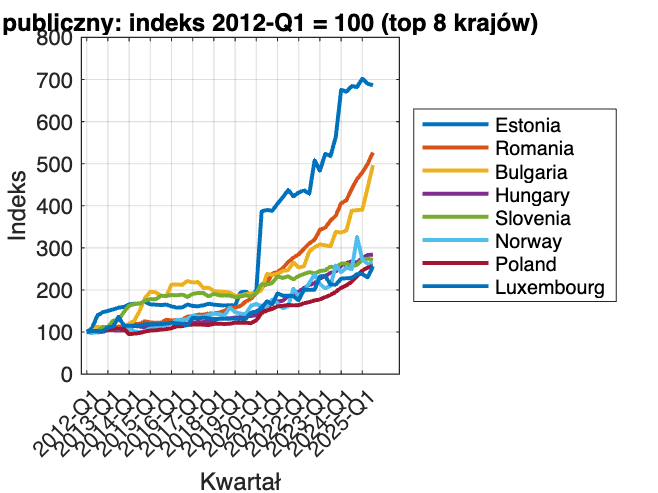


% Zmiana skumulowana od pierwszego do ostatniego kwartału (%)
growthPct = (debtValues(:,end) ./ debtValues(:,1) - 1) * 100;

% Usunięcie ewentualnych problematycznych obserwacji
validIdx = isfinite(growthPct) & isfinite(debtValues(:,1)) & debtValues(:,1) > 0;

growthPctValid = growthPct(validIdx);
countriesValid = countries(validIdx);
debtValuesValid = debtValues(validIdx,:);

[~, ordIndex] = sort(debtIndex(:,end), 'descend', 'MissingPlacement', 'last');
topN = min(8, numel(countries));
topIdx = ordIndex(1:topN);

figure('Name','Indeks długu - najbardziej dynamiczne kraje');
plot(debtIndex(topIdx,:)', 'LineWidth', 1.8);
grid on;
title(sprintf('Dług publiczny: indeks 2012-Q1 = 100 (top %d krajów)', topN));
xlabel('Kwartał');
ylabel('Indeks');
xticks(1:4:numel(quarters));
xticklabels(quarters(1:4:end));
xtickangle(45);
legend(countries(topIdx), 'Location', 'eastoutside');

nexttile;

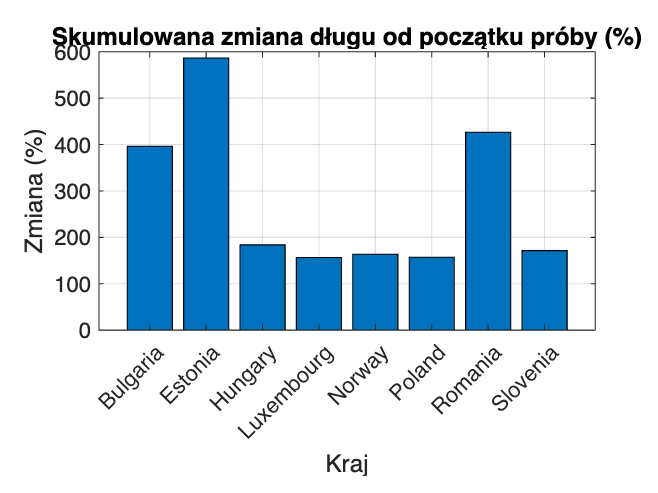

bar(categorical(countriesValid(topIdx)), growthPctValid(topIdx));
grid on;
title('Skumulowana zmiana długu od początku próby (%)');
xlabel('Kraj');
ylabel('Zmiana (%)');
xtickangle(45);

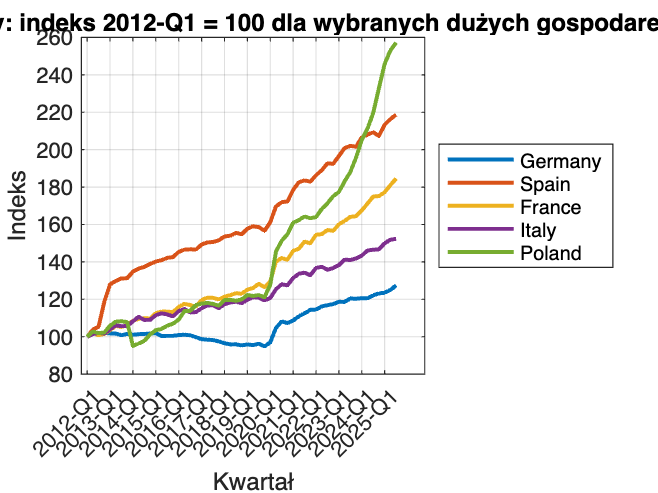

economies = ["Poland","Germany","France","Italy","Spain"];
maskEconomies = ismember(countries, economies);
if any(maskEconomies)
    figure('Name','Indeks długu - wybrane duże gospodarki');
    plot(debtIndex(maskEconomies,:)', 'LineWidth', 1.8);
    grid on;
    title('Dług publiczny: indeks 2012-Q1 = 100 dla wybranych dużych gospodarek');
    xlabel('Kwartał');
    ylabel('Indeks');
    xticks(1:4:numel(quarters));
    xticklabels(quarters(1:4:end));
    xtickangle(45);
    legend(countries(maskEconomies), 'Location', 'eastoutside');
end

## 5. Dynamika rok do roku

Dane kwartalne warto oceniać także przez zmianę rok do roku: porównujemy dany kwartał z analogicznym kwartałem poprzedniego roku.

yoyChange = NaN(size(debtValues));
yoyChange(:,5:end) = 100 * (debtValues(:,5:end) ./ debtValues(:,1:end-4) - 1);

latestYoY = yoyChange(:,end);
yoyTable = table(countries, latestYoY, ...
    'VariableNames', {'Country','LatestYoYChangePct'});
disp('--- Ostatnia dynamika rok do roku (%) ---');

--- Ostatnia dynamika rok do roku (%) ---


disp(sortrows(yoyTable, 'LatestYoYChangePct', 'descend'));

       Country       LatestYoYChangePct
    _____________    __________________

    "Bulgaria"              27.717     
    "Romania"                19.63     
    "Poland"                17.093     
    "Lithuania"             13.934     
    "Luxembourg"            12.208     
    "Malta"                 10.326     
    "Slovakia"              8.3838     
    "Portugal"              8.1141     
    "Finland"               7.5273     
    "Sweden"                6.5255     
    "Austria"               6.3618     
    "Slovenia"              6.0682     
    "Hungary"               5.8428     
    "Belgium"               5.7065     
    "Norway"                5.6511     
    "France"                5.4744     
    "Netherlands"           5.0992     
    "Czechia"               5.0689     
    "Spain"                 4.4995     
    "Germany"               4.3417     
    "Italy"                 3.9826     
    "Croati

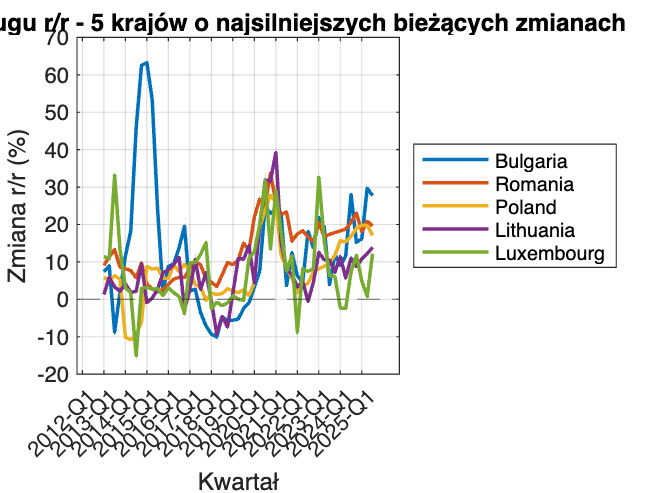


[~, ordYoY] = sort(abs(latestYoY), 'descend', 'MissingPlacement', 'last');
topN = min(5, numel(countries));
topIdx = ordYoY(1:topN);

figure('Name','Dynamika rok do roku - kraje o najsilniejszych zmianach');
plot(yoyChange(topIdx,:)', 'LineWidth', 1.6);
grid on;
title(sprintf('Dynamika długu r/r - %d krajów o najsilniejszych bieżących zmianach', topN));
xlabel('Kwartał');
ylabel('Zmiana r/r (%)');
xticks(1:4:numel(quarters));
xticklabels(quarters(1:4:end));
xtickangle(45);
yline(0,'--');
legend(countries(topIdx), 'Location', 'eastoutside');

## 6. Zmienność dynamiki - które kraje są najbardziej niestabilne

Odchylenie standardowe dynamiki r/r traktujemy jako prostą miarę niestabilności zmian zadłużenia.

volatilityYoY = std(yoyChange, 0, 2, 'omitnan');
volTable = table(countries, volatilityYoY, ...
    'VariableNames', {'Country','YoYVolatility'});
volTable = sortrows(volTable, 'YoYVolatility', 'descend');

disp('--- Zmienność dynamiki r/r ---');

--- Zmienność dynamiki r/r ---


disp(volTable);

       Country       YoYVolatility
    _____________    _____________

    "Estonia"           27.906    
    "Bulgaria"          16.801    
    "Slovenia"          10.454    
    "Luxembourg"        9.8674    
    "Lithuania"         8.8873    
    "Norway"            8.6301    
    "Czechia"           8.4718    
    "Cyprus"            8.4089    
    "Poland"            8.3928    
    "Romania"           7.5974    
    "Latvia"             7.039    
    "Malta"              6.861    
    "Slovakia"          6.7343    
    "Denmark"              6.2    
    "Sweden"            5.8914    
    "Hungary"           5.7071    
    "Spain"             5.5142    
    "Croatia"           4.4097    
    "Ireland"           4.2912    
    "Austria"            4.258    
    "Netherlands"       4.1613    
    "Germany"           3.8142    
    "Finland"           3.4569    
    "Greece"            3.1169    
    "Portugal"       

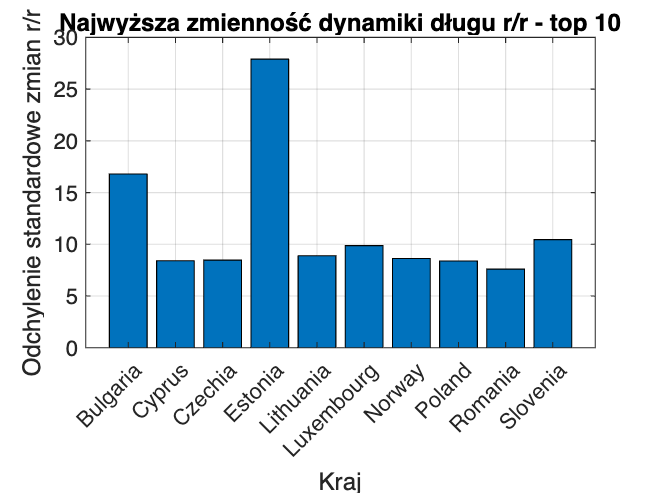


topN = min(10, height(volTable));
figure('Name','Zmienność dynamiki - top 10');
bar(categorical(volTable.Country(1:topN)), volTable.YoYVolatility(1:topN));
grid on;
title(sprintf('Najwyższa zmienność dynamiki długu r/r - top %d', topN));
xlabel('Kraj');
ylabel('Odchylenie standardowe zmian r/r');
xtickangle(45);

## 7. Heatmapa indeksu

Heatmapa pozwala szybko zobaczyć, które kraje przez większość okresu znajdowały się blisko punktu startowego, a które weszły na wyraźnie wyższe ścieżki zadłużenia.

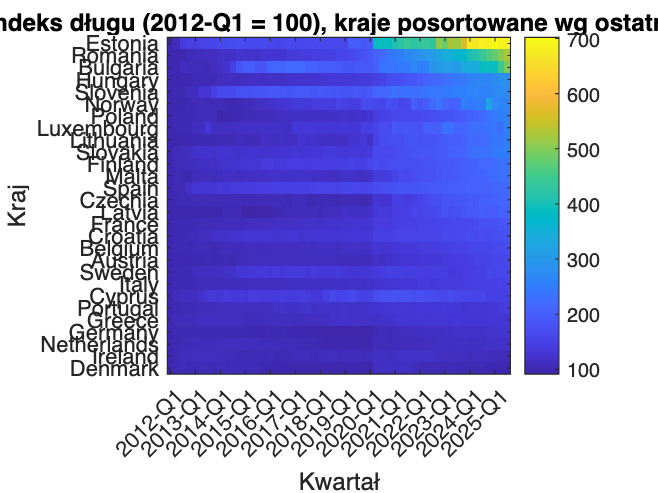

[~, sortIdx] = sort(debtIndex(:,end), 'descend', 'MissingPlacement', 'last');
figure('Name','Heatmapa indeksu');
imagesc(debtIndex(sortIdx,:));
colorbar;
title('Heatmapa: indeks długu (2012-Q1 = 100), kraje posortowane wg ostatniego kwartału');
xlabel('Kwartał');
ylabel('Kraj');
yticks(1:numel(countries));
yticklabels(countries(sortIdx));
xticks(1:4:numel(quarters));
xticklabels(quarters(1:4:end));
xtickangle(45);

## 8. Ostatni kwartał vs średnia z całego okresu

To proste porównanie mówi, czy bieżący poziom długu jest relatywnie wysoki lub niski względem przeciętnej ścieżki badanego kraju.

relativeToMean = 100 * (lastDebt ./ meanDebt - 1);
relativeTable = table(countries, relativeToMean, ...
    'VariableNames', {'Country','LastVsMeanPct'});
relativeTable = sortrows(relativeTable, 'LastVsMeanPct', 'descend');

disp('--- Ostatni kwartał względem średniej z okresu (%) ---');

--- Ostatni kwartał względem średniej z okresu (%) ---


disp(relativeTable);

       Country       LastVsMeanPct
    _____________    _____________

    "Romania"            142.23   
    "Estonia"            123.65   
    "Bulgaria"           119.39   
    "Poland"             80.984   
    "Hungary"            77.749   
    "Lithuania"          72.881   
    "Luxembourg"         63.801   
    "Norway"             63.126   
    "Malta"              60.515   
    "Slovakia"            60.44   
    "Czechia"            59.465   
    "Latvia"             53.218   
    "Finland"            48.056   
    "France"             38.829   
    "Slovenia"           36.967   
    "Austria"            34.913   
    "Spain"              34.517   
    "Belgium"            34.373   
    "Croatia"            27.093   
    "Italy"                23.9   
    "Germany"            19.791   
    "Sweden"             17.426   
    "Portugal"           16.799   
    "Netherlands"        11.285   
    "Greece"         

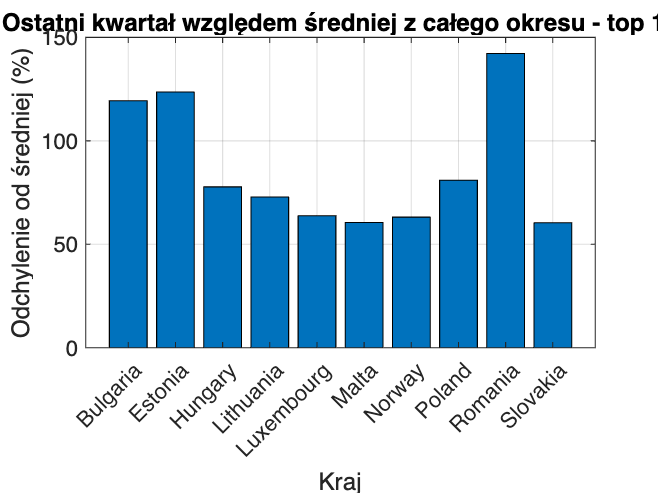


topN = min(10, height(relativeTable));
figure('Name','Ostatni kwartał vs średnia - top 10');
bar(categorical(relativeTable.Country(1:topN)), relativeTable.LastVsMeanPct(1:topN));
grid on;
title(sprintf('Ostatni kwartał względem średniej z całego okresu - top %d', topN));
xlabel('Kraj');
ylabel('Odchylenie od średniej (%)');
xtickangle(45);
yline(0,'--');

## 9. Proste porównanie grup krajów

Tworzymy 3 orientacyjne grupy: - Europa Północno-Zachodnia, - Europa Południowa, - Europa Środkowo-Wschodnia. To nie jest klasyfikacja formalna, ale pomaga zobaczyć szersze wzorce.

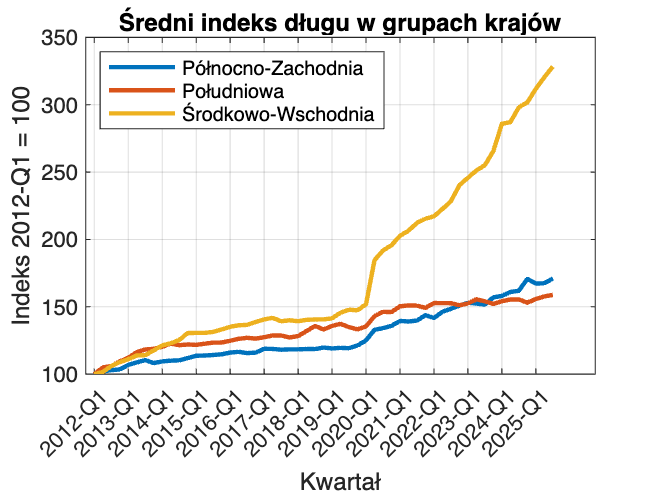

groupNW = ["Belgium","Denmark","Germany","Ireland","France","Luxembourg", ...
    "Netherlands","Austria","Finland","Sweden","Norway"];
groupSouth = ["Greece","Spain","Italy","Portugal","Cyprus"];
groupCEE = ["Bulgaria","Czechia","Estonia","Croatia","Latvia","Lithuania", ...
    "Hungary","Poland","Romania","Slovenia","Slovakia"];

maskNW = ismember(countries, groupNW);
maskSouth = ismember(countries, groupSouth);
maskCEE = ismember(countries, groupCEE);

avgIndexNW = mean(debtIndex(maskNW,:), 1, 'omitnan');
avgIndexSouth = mean(debtIndex(maskSouth,:), 1, 'omitnan');
avgIndexCEE = mean(debtIndex(maskCEE,:), 1, 'omitnan');

figure('Name','Porównanie grup krajów');
plot(avgIndexNW, 'LineWidth', 2); hold on;
plot(avgIndexSouth, 'LineWidth', 2);
plot(avgIndexCEE, 'LineWidth', 2);
grid on;
title('Średni indeks długu w grupach krajów');
xlabel('Kwartał');
ylabel('Indeks 2012-Q1 = 100');
xticks(1:4:numel(quarters));
xticklabels(quarters(1:4:end));
xtickangle(45);
legend({'Północno-Zachodnia','Południowa','Środkowo-Wschodnia'}, ...
    'Location','northwest');
hold off;

## 10. Wnioski

Podstawowe wnioski z prostej analizy eksploracyjnej:

cumChangePct = 100 * (debtValues(:,end) ./ debtValues(:,1) - 1);
cumChangeTable = table(countries, cumChangePct, ...
    'VariableNames', {'Country','CumulativeChangePct'});
cumChangeTable = sortrows(cumChangeTable, 'CumulativeChangePct', 'descend');
[~, idxMaxCum] = max(cumChangePct);
[~, idxMinCum] = min(cumChangePct);
[~, idxMaxVol] = max(volatilityYoY);
[~, idxMinVol] = min(volatilityYoY);
[~, idxMaxLastYoY] = max(latestYoY);
[~, idxMinLastYoY] = min(latestYoY);

fprintf('1. Najsilniejszy wzrost nominalnego długu od początku próby odnotowano w kraju: %s (%.1f%%).\n', ...
    countries(idxMaxCum), cumChangePct(idxMaxCum));

1. Najsilniejszy wzrost nominalnego długu od początku próby odnotowano w kraju: Estonia (586.3%).


fprintf('2. Najmniejszą skumulowaną zmianę odnotowano w kraju: %s (%.1f%%).\n', ...
    countries(idxMinCum), cumChangePct(idxMinCum));

2. Najmniejszą skumulowaną zmianę odnotowano w kraju: Denmark (0.0%).


fprintf('3. Największą zmienność dynamiki r/r miał kraj: %s (%.2f).\n', ...
    countries(idxMaxVol), volatilityYoY(idxMaxVol));

3. Największą zmienność dynamiki r/r miał kraj: Estonia (27.91).


fprintf('4. Najbardziej stabilny przebieg dynamiki r/r miał kraj: %s (%.2f).\n', ...
    countries(idxMinVol), volatilityYoY(idxMinVol));

4. Najbardziej stabilny przebieg dynamiki r/r miał kraj: Italy (1.62).


fprintf('5. Najwyższa ostatnia dynamika r/r wystąpiła w kraju: %s (%.1f%%).\n', ...
    countries(idxMaxLastYoY), latestYoY(idxMaxLastYoY));

5. Najwyższa ostatnia dynamika r/r wystąpiła w kraju: Bulgaria (27.7%).


fprintf('6. Najsłabsza ostatnia dynamika r/r wystąpiła w kraju: %s (%.1f%%).\n', ...
    countries(idxMinLastYoY), latestYoY(idxMinLastYoY));

6. Najsłabsza ostatnia dynamika r/r wystąpiła w kraju: Cyprus (-5.0%).



fprintf(['- W wielu krajach poziom długu w 2025 roku pozostaje wyraźnie wyższy niż na początku próby,\n' ...
         '  co sugeruje trwałe przesunięcie ścieżki zadłużenia po kolejnych szokach makroekonomicznych.\n']);

- W wielu krajach poziom długu w 2025 roku pozostaje wyraźnie wyższy niż na początku próby,
  co sugeruje trwałe przesunięcie ścieżki zadłużenia po kolejnych szokach makroekonomicznych.


fprintf(['- Kraje Europy Środkowo-Wschodniej częściej pokazują szybkie wzrosty indeksu, co może wynikać\n' ...
         '  z niższej bazy początkowej i silnego dostosowania fiskalnego w kolejnych latach.\n']);

- Kraje Europy Środkowo-Wschodniej częściej pokazują szybkie wzrosty indeksu, co może wynikać
  z niższej bazy początkowej i silnego dostosowania fiskalnego w kolejnych latach.


fprintf(['- Część dużych gospodarek zachodnich charakteryzuje się mniejszą zmiennością dynamiki,\n' ...
         '  ale przy nadal wysokim nominalnym poziomie długu.\n']);

- Część dużych gospodarek zachodnich charakteryzuje się mniejszą zmiennością dynamiki,
  ale przy nadal wysokim nominalnym poziomie długu.
